%https://www.gaussianwaves.com/2019/11/shannons-limit-on-power-efficiency/
for i = 1:1
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR_db] = GenerateSignal("11101", 0.2)
end

idealSignal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


noisySignal =     0.0168    0.0276   -0.0038    0.0318    0.0166    0.0242    0.0110    0.0505    0.0134    0.0381    0.0450    0.0455    0.0350    0.0949    0.0655    0.0737    0.0878    0.0613    0.1115    0.0934    0.1098    0.1531    0.1609    0.1569    0.1764    0.1879    0.1811    0.1950    0.2319    0.2394    0.2576    0.2824    0.2927    0.2852    0.3094    0.3345    0.3421    0.3501    0.3725    0.3935    0.3907    0.3913    0.4184    0.4151    0.4065    0.4074    0.4136    0.4121    0.4002    0.4161


discretizedSignal =     0.0168    0.0450    0.1098    0.2576    0.3907    0.4267    0.3051    0.1848    0.1535    0.2188    0.3471    0.4348    0.3612    0.3055    0.3351    0.4042    0.3575    0.1764    0.0349    0.0592    0.2475    0.5000    0.5454    0.4285    0.2939    0.3227    0.3333    0.2413    0.0015   -0.2020   -0.1806    0.1133    0.3583    0.4394    0.2901    0.2357    0.2638    0.3549    0.4512    0.3408    0.2296    0.2037    0.2336    0.3969    0.4956    0.4971    0.3558    0.1617    0.0066    0.0552


ADCsignal =      3     8    20    47    71    78    56    34    28    40    63    79    66    56    61    74    65    32     6    11    45    91    99    78    54    59    61    44     0     0     0    21    65    80    53    43    48    65    82    62    42    37    43    72    90    91    65    29     1    10


ADCpreambule =     36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36


signalSNR_db = -9.4000

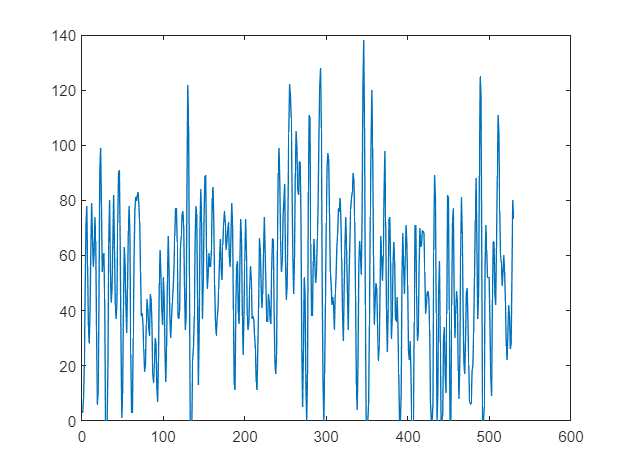


plot(ADCsignal)

fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
yOneOne = GenerateConv(ADCsignal, idealPreambule) %diferencijuotas

yOneOne =      0     0     0     0     0     0     0     0     0     0     3    11    31    78   149   224   272   286   267   236   224   255   307   382   474   560   594   574   505   424   380   429   528   628   692   717   673   584   456   352   264   250   338   490   586   646   651   616   587   613


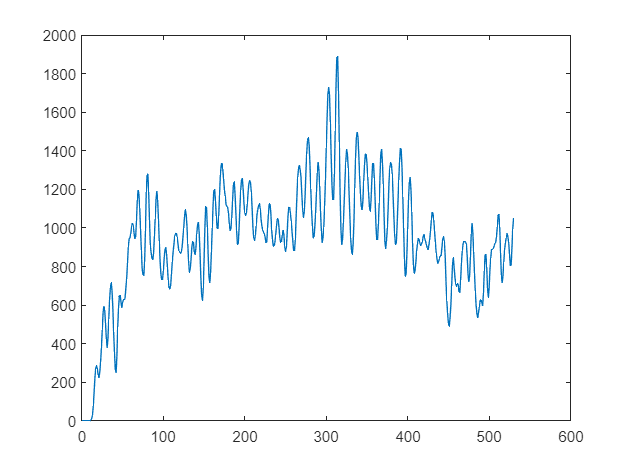

plot(yOneOne)

signalSNR_db

signalSNR_db = -9.4000

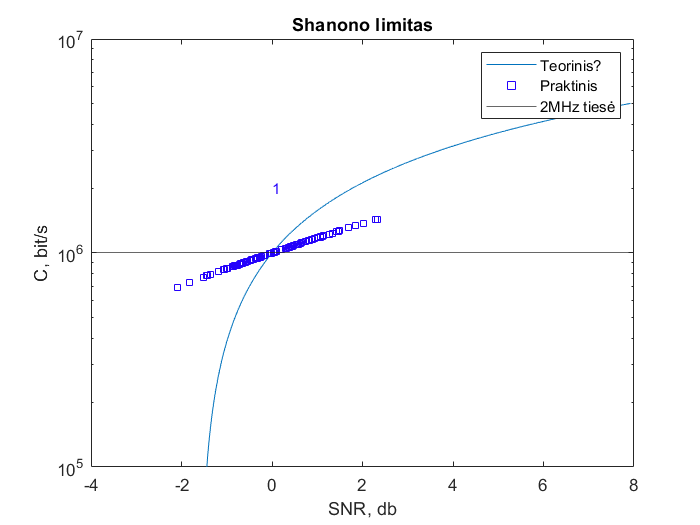


B = 1E6;
%{
for i = 0.5:0.1:1.4
    [idealSignal3, noisySignal3, discretizedSignal3, ADCsignal3, ADCpreambule3, signalSNR_db] = GenerateSignal(dataSend, i);
    ADCsignal2 = [ADCsignal2, ADCsignal3];

    sugeneruoti_triuksmai_db = [sugeneruoti_triuksmai_db, signalSNR_db];
    shanono_bit_capacity = [shanono_bit_capacity, log2(1+db2pow(signalSNR_db))];
end
%}

%Teorines
teor_sugeneruoti_triuksmai_db = [];
teor_shanono_bit_capacity = [];
for i = 0.1:0.001:5
    signalSNR_db = pow2db(i);
    teor_sugeneruoti_triuksmai_db = [teor_sugeneruoti_triuksmai_db, pow2db((2^db2pow(signalSNR_db)-1)/db2pow(signalSNR_db))];
    teor_shanono_bit_capacity = [teor_shanono_bit_capacity, i]; %log2(1+db2mag(signalSNR_db))]%[teor_shanono_bit_capacity, (2^db2pow(signalSNR_db)-1)/db2pow(signalSNR_db)]; %log2(1+db2mag(signalSNR_db))];
end

%Praktines
shanono_bit_capacity = [];
sugeneruoti_triuksmai_db = [];

sugeneruoti_triuksmai_db = kiekvienas_snr_db;
shanono_bit_capacity = B*log2(1+db2pow(kiekvienas_snr_db));
vidurkinti_triuksmai = mean(sugeneruoti_triuksmai_db, 2)';
vidurkinti_capacity = mean(shanono_bit_capacity, 2)';

fmt = ['*','o','^','.','+','x','s','p','h', '*','o','^','.','+','x','s','p','h', '*','o','^','.','+','x','s','p','h'];
figure
semilogy(teor_sugeneruoti_triuksmai_db, teor_shanono_bit_capacity*B)
hold on
for i = 7:7%2:size(shanono_bit_capacity, 1)
    nauja_spalva = [rand, rand, rand];
    scatter(sugeneruoti_triuksmai_db(i, :), shanono_bit_capacity(i, :), 30, nauja_spalva,fmt(i))
    text(vidurkinti_triuksmai(1, i), vidurkinti_capacity(1, i)*2, string(neteisingi_d(i)), 'FontSize',9, 'Color', nauja_spalva)
end

yline(1e6)
title("Shanono limitas")
xlabel("SNR, db")
ylabel("C, bit/s")
legend("Teorinis?", "Praktinis", "2MHz tiesė")
hold off

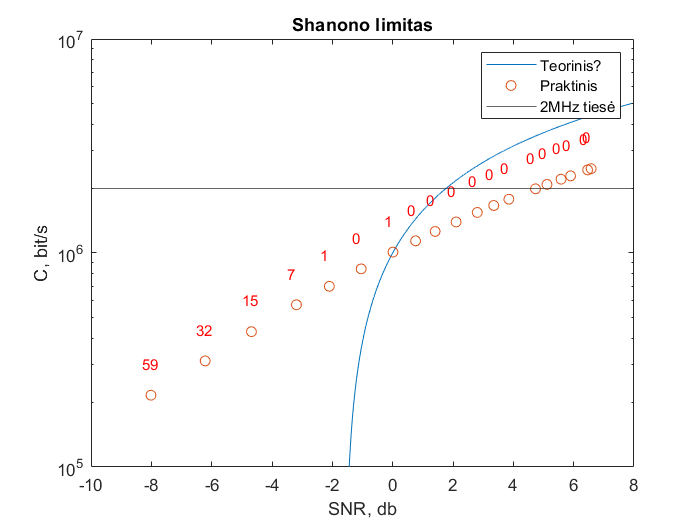

figure
semilogy(teor_sugeneruoti_triuksmai_db, teor_shanono_bit_capacity*B)
hold on
scatter(vidurkinti_triuksmai, vidurkinti_capacity)
text(vidurkinti_triuksmai-0.3, vidurkinti_capacity*1.4, string(neteisingi_d), 'FontSize',9, 'Color', 'r')
yline(1e6)
title("Shanono limitas")
xlabel("SNR, db")
ylabel("C, bit/s")
legend("Teorinis?", "Praktinis", "2MHz tiesė")
hold off

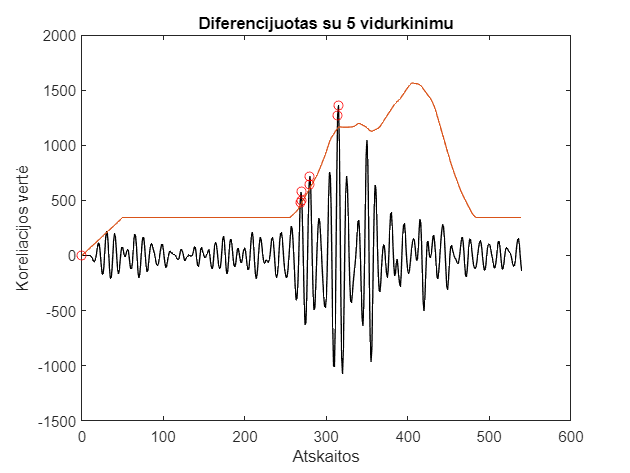

pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";
ma_ilgis = 5;

neteisingi = zeros(1, 19);
vienetu_generuoti = 100;

kiekvienas_snr_db = zeros(19, vienetu_generuoti);

generuojama_amplitude_viso = 0.2:0.05:1.1;
for generuojama_amplitude_index = 1:19
    generuojama_amplitude = generuojama_amplitude_viso(generuojama_amplitude_index);

    for i = 1:vienetu_generuoti
            [idealSignal, noisySignal, discretizedSignal, ADCsignal2, ADCpreambule, signalSNR_db] = GenerateSignal(dataSend, generuojama_amplitude);
            kiekvienas_snr_db(generuojama_amplitude_index, i) = signalSNR_db;
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
    
            ADCsignal2_ma = GenerateMA(ADCsignal2, ma_ilgis);
            pastumtas_ma = [zeros(1, pastumimasN), ADCsignal2_ma(1:length(ADCsignal2_ma)-pastumimasN)];
            diferencijuotasPilnas_ma = ADCsignal2_ma - pastumtas_ma;
            %diferencijuotasPilnas = ADCsignal2_ma - pastumtas;
            
            %diferencijuotasPilnas_ma = GenerateMA(diferencijuotasPilnas, ma_ilgis);
            %diferencijuotaPreambule_ma = GenerateMA(diferencijuotaPreambule, ma_ilgis);
            %idealPreambule_ma = GenerateMA(idealPreambule, ma_ilgis);
           
            %y = GenerateConv(y, yy); %diferencijuotas DVIGUBAI
            %y_d = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
            %y_nd = GenerateConv(ADCsignal2, idealPreambule); %Nediferencijuoptas
            
            %y_d = GenerateConv(diferencijuotasPilnas_ma, diferencijuotaPreambule_ma); %Diferencijuotas
            y_d = GenerateConv(diferencijuotasPilnas_ma, diferencijuotaPreambule); %Diferencijuotas
            %y_nd = GenerateConv(ADCsignal2_ma, idealPreambule_ma); %Nediferencijuoptas
            %y_nd = GenerateConv(ADCsignal2_ma, idealPreambule); %Nediferencijuoptas
            
            eng1 = zeros(1, length(y_d));
            for ii = 50:length(y_d)
                eng1(ii) = sum(abs(ADCsignal2(ii-50+1:ii) .* ADCsignal2(ii-50+1:ii)))/50;
            end
            
            p1 = [-2.10864068822485e-06,	0.121214240814902,	-113.303462094050]; %Vidurkio funkcija
            approx = zeros(1, length(eng1));
            for ii = 1:length(eng1)
                if(eng1(ii) < 3994.28)
                    approx(ii) = 343.218;
                else
                    approx(ii) = eng1(ii)^2*p1(1)+eng1(ii)*p1(2)+p1(3);
                end
            end
            
            pataikytas313 = 0;
            pataikytaFake = 0;
            suKirtimais = GenerateMA(approx, 50);
            kirtimaiX = zeros(1, length(suKirtimais));
            kirtimaiY = zeros(1, length(suKirtimais));
            for ii = 100:length(suKirtimais)
                if(y_d(ii) >= suKirtimais(ii))
                    if ii > 310 && ii < 316
                        pataikytas313 = 1;
                    end

                    if ii < 310
                        pataikytaFake = 1;
                    end
                    kirtimaiX(ii) = ii;
                    kirtimaiY(ii) = y_d(ii);
                end
            end

            if pataikytaFake == 1 || pataikytas313 == 0
                neteisingi(generuojama_amplitude_index) = neteisingi(generuojama_amplitude_index) + 1;
            end
    end
end

figure
plot(y_d, "black")
hold on
plot(suKirtimais)
scatter(kirtimaiX, kirtimaiY, 'red', 'o')
title("Diferencijuotas su 5 vidurkinimu")
xlabel("Atskaitos")
ylabel("Koreliacijos vertė")
hold off

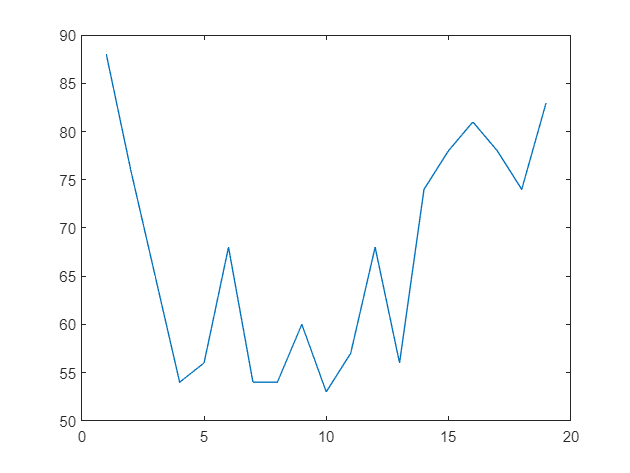


figure
plot(neteisingi)

%shanono sudai

x = [];
y = [];

R = 1e6;
B = 2e6;
xx = [];
yy = [];

for i = -10:0.2:40
    x = [x, i];
    db2mag(i);
    y = [y, log2(1+db2mag(i))];

    xx = [xx, i];
    yy = [yy, B * log2(1+db2pow(i))];


end
figure
semilogy(x, y)

figure


figure
semilogy(xx, yy)
hold on
k =0.1:0.001:15; EbN0=(2.^k-1)./k;
semilogy(10*log10(EbN0),k);
hold off
xlabel('E_b/N_o (dB)');ylabel('Spectral Efficiency (\eta)');
title('Channel Capacity & Power efficiency limit')
hold on;grid on; xlim([-2 20]);ylim([0.1 10]);
yL = get(gca,'YLim');
line([-1.59 -1.59],yL,'Color','r','LineStyle','--');
